clear all, close all, clc

############### ############### ############### ############### 

## Prob-7.1a

Given,


$$f\left(t\right)=2\ldotp 66\;t^{-1\ldotp 2\;}$$


Now, for finding total energy emitted by b and g- over t = [1, 1e6] s

syms t                      % time; s
f_t = 2.66 *t^-1.2;             % Avg. E at t; Way-Wigner; MeV/fs.s
f_tv = int(f_t, t, 1, 1e6);     % total energy ; MeV
f_tv = double(f_tv)             % MeV

f_tv = 12.4608

Now, the 2/3 of this energy be-

E = 2/3 *f_tv               % MeV

E = 8.3072

Then, let's find an integral expression for this, in t0

syms t0 
E_t = int(f_t, t, 1, t0)

$$E\_t = \frac{133}{10}-\frac{133}{10\,{t_{0}}^{1/5}}$$

Now, let's solve this expression to find the time to achieve that energy

eqn = E == E_t;
t0 = solve(eqn, t0);
t0 = double(t0)           % sec

t0 = 134.1359

(Ans)

############### ###############

## Prob-7.1b

Given,

$n_f =\frac{P_0 }{Q}\;{\textrm{dt}}^{\prime }$        $n_f =$ no. of fissions at interval dt' 


$$P_d =n_f \;f\left(T-t^{\prime } \right)\;$$
    

syms P0             % constant power of operation; W
syms Q              % fission E; MeV/fs
syms T              % upper limit; sec

Now, it was given-

f_t = 2.66 *t^-1.2;             % Avg. E at t; Way-Wigner

The Way-Wigner formula has been validated for $t=\left\lbrack 1\;\textrm{to}\;{10}^6 \right\rbrack$s. So, we can assume t' = 1 sec, before which, no fission has occured. 

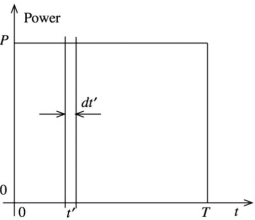

Then, let's find teh decay up-to time T

P_d = P0/Q *int(f_t, t, 1, T)       % MeV/s

$$P\_d = -\frac{P_{0}\,\left(\frac{133}{10\,T^{1/5}}-\frac{133}{10}\right)}{Q}$$

Which is, basically-

$P_d \left(t\right)=\frac{P_0 }{Q}\;\frac{2\ldotp 66}{0\ldotp 2}\;\left(1-T^{-0\ldotp 2} \right)$    [MeV/s] 

############### ###############

## Prob-7.1c

Q = 200;            % MeV/fsn

Now, when $T\to \infty$, we have-

T = inf;

Then, let's evaluate the expression got at the segment before

P_di = eval(P_d)        % MW_th

$$P\_di = \frac{133\,P_{0}}{2000}$$

(Ans)

so, it is seen that, it is 6.65% of the rated power P0

############### ############### ############### ############### 

## Prob-7.2a

Now, from eq-3 in **ANS 5.1**, we have-


$$P_d {\left(t,T\right)}=\int_0^T \frac{P_i {\left(T^{\prime } \right)}}{Q_i }f{\left(t+t-T^{\prime } \right)}dT\prime$$


Let, $t+T-T^{\prime } =t\prime$    So, $-dT^{\prime } =dt$

    $t=$ ongoing time (after SD); $T=$ opearation time before SD

Limits, $T^{\prime } =T;T^{\prime } =0$

Then, for constant power and certain RN group i 


$$P_d {\left(t,T\right)}=-\frac{P}{Q}\int_0^T f{\left(t\prime \right)}\ dt\prime$$


Or, $P_d {\left(t,T\right)}=-\frac{P}{Q}\int_0^T 2.66\ {t^{\prime } }^{-1.2} \ dt\prime$

Or, $P_d {\left(t,T\right)}=+\frac{P}{Q}\frac{2.66}{0.2}\ {{\left({t^{\prime } }^{-0.2} \right∣}}_0^T$

Or, $P_d {\left(t,T\right)}=\frac{P}{Q}\frac{2.66}{0.2}\ {{\left({\left(t+T-T\prime \right)}^{-0.2} \right∣}}_0^T$

Or, $P_d {\left(t,T\right)}=\frac{P}{Q}\frac{2.66}{0.2}\ {\left({{\left(t+T-T\right)}}^{-0.2} -{\left(t+T-0\right)}^{-0.2} \right)}$

Or, $P_d {\left(t,T\right)}=\frac{P}{Q}\frac{2.66}{0.2}\ {\left(t^{-0.2} -{\left(t+T\right)}^{-0.2} \right)}$         (Eq-1)

(Shown)

As from ANS 5.1, equation 6, we have-

             (Eq-2)

Comparing eq-1 and eq-2, we can write

$f{\left(t,T\right)}=\frac{2.66}{0.2}\ {\left(t^{-0.2} -{\left(t+T\right)}^{-0.2} \right)}$         (Eq-3)

Now, the eq-8 of ANS-5.1, we have-


$$f{\left(t,\infty \right)}=f{\left(t,\infty \right)}-f\left(t+T,\ \infty \right)$$


Here, 


$$f{\left(t,\infty \right)}=\frac{2.66}{0.2}\ {\left(t^{-0.2} -{\left(t+\infty \right)}^{-0.2} \right)}$$


Or, $f{\left(t,\infty \right)}=\frac{2.66}{0.2}\ {\left(t^{-0.2} \right)}$

And, $f{\left(t+T,\infty \right)}=\frac{2.66}{0.2}\ {\left({\left(t+T\right)}^{-0.2} -{\left(t+T+\infty \right)}^{-0.2} \right)}$

Or, $f{\left(t+T,\infty \right)}=\frac{2.66}{0.2}{\left({{\left(t+T\right)}}^{-0.2} \right)}$

Thus, $f{\left(t,\infty \right)}-f{\left(t+T,\ \infty \right)}=\frac{2.66}{0.2}\ {\left(t^{-0.2} -{{\left(t+T\right)}}^{-0.2} \right)}$

As, we found, in eq-3


$$f{\left(t,T\right)}=\frac{2.66}{0.2}\ {\left(t^{-0.2} -{\left(t+T\right)}^{-0.2} \right)}$$


So, $f{\left(t,\infty \right)}\;=f{\left(t,\infty \right)}-f\left(t+T,\ \infty \right)$

Then, the ANS-5.1 Eq-8 is **Validated**

############### ###############

## Prob-7.2b

We have-

syms P0             % constant power of operation; W
syms Q              % fission E; MeV/fs
syms T              % SD time; sec
syms t

The given Way-Wigner Formula


$$P_d \left(t,T\right)=\frac{P_0 }{Q}\;\frac{2\ldotp 66}{0\ldotp 2}\;\left(t^{-0\ldotp 2} -{\left(t+T\right)}^{-0\ldotp 2} \right)\;$$


P_d = P0/Q *13.3 *(t^-0.2 -(t+T)^-0.2 );    % MeV/s

When, $T=\infty$, we have-

P_di = P0/Q *13.3 *(t^-0.2)         % MeV/s

$$P\_di = \frac{133\,P_{0}}{10\,Q\,t^{1/5}}$$

The fraction of decay power to SS power-


$$g\left(t,\infty \;\right)=\frac{P_d \left(t,T\right)}{P_0 }=\frac{13\ldotp 3\;t^{-0\ldotp 2} }{Q}\;$$


then,

Q = 200;            % MeV/fsn
g = 13.3*t^-0.2/Q;  % decay heat fraction

Now, for plotting-

t = logspace(0,6, 1e4+1);
gv = eval(g);

From ANS-1 Table 5, we get-

tA = [1e0,       1e1,    1e2,   1e3,    1e4,   1e5,     1e6 ]; 
f_tA = [1.24e1,  9.49e0, 6.2e0, 3.8e0, 1.91e0, 9.72e-1, 5.55e-1];
gA  = f_tA/Q

gA =     0.0620    0.0474    0.0310    0.0190    0.0095    0.0049    0.0028


Let's plot it-

figure(1)
semilogx(t, gv), grid minor, hold on
semilogx(tA, gA, '*')
xlabel('time, t'); ylabel('fraction, g')

So, we can see that values- got from the expression and that from ANS-5.1, T5 is almost similar. 

############### ###############

## Prob-7.2c

For Fukushima Daiichi Incident, given-

t = 30 *60^2*24;        % cooling time; sec
T = 18* 60^2*24*30;     % prior operating time; s
Q = 200;                % MeV/fsn

Now, from ANS-5.1, we can write-


$$g=\frac{1}{Q}\left\lbrack 13\ldotp 3\;\left(t^{-0\ldotp 2} -{\left(t+T\right)}^{-0\ldotp 2} \right)\right\rbrack$$


g = 1/Q *13.3 *(t^-0.2 -(t+T)^-0.2 )        % DH fraction

g = 0.0015

For FD U-3 -

P0 = 2352;          % rated power; MW
P_d = P0 *g         % decay power at given time; MW

P_d = 3.6303

(Ans)

############### ###############

## Prob-7.2d

**i)**

From RSANS, we know, 1W of thermal energy produce 2Ci of radioactivity. So-

A_SD = P0*2          % radioactivity, at Shut Down; MCi

A_SD = 4704

(Ans)

**ii)**

A_FP = P_d*2         % radioactivity, after 30 days; MCi

A_FP = 7.2607

(Ans)

############### ############### ############### ############### 

## Prob-7.4a

Given,

$D_{\gamma \;} =\phi \;E_{\gamma \;} \;\frac{\mu }{\rho }\;$        $D_{\gamma \;} =$ dose from gamma; $\phi =$ flux [no./cm^2.s]

    $\frac{\mu }{\rho }=$ MEAC (mass energy attenuation coefficient); $E_{\gamma \;} =$ gamma energy

S = 1;              % activity; Ci
S = S*37e9;         % activity; #/s
R = 0.1*100;        % radius; cm

So, the flux-

Ar = 4*pi*R^2;      % area; cm^2
ph = S/Ar           % flux; #/cm^2.s

ph = 2.9444e+07

Then, the gamma energy from Co-60 are-

E1 = 1.33;          % g-energy 1, Co-60; MeV
E2 = 1.17;          % MeV
E = (E1+E2)/2       % effective E, Co-60; MeV

E = 1.2500

 J_MeV = 1.6e-13;   % J/MeV
E = E *J_MeV        % g-energy; J

E = 2.0000e-13

From attached table, we find, the $\frac{\mu }{\rho }$ for tissue-

mu_rh = 0.0288;     % MEAC; cm^2/g

Then, let's find the dose

Dr = ph *E *mu_rh     % dose rate, tisuse; J/g.s

Dr = 1.6960e-07

Dr = Dr *1e3*60^2     % ; J/kg.hr; Gy/hr

Dr = 0.6105

(Ans)

Q = 1;                  % quality factor
Dr = Dr*Q*1e3           % dose rate, tissue; mSv/hr

Dr = 610.5438

Then, for annual total exposure, we get-

Dr_A = Dr *24*365        % mSv/y

Dr_A = 5.3484e+06

Now, according to 10 CFR, part 20.1201

Dr_OA = 50;             % occupational DR limit; mSv/y
r1 = Dr_A /Dr_OA        % 

r1 = 1.0697e+05

Here, r1 indicates the times, the annual dose-rate in the given situation, higher than the occupational dose-rate limit

Dr_b = 2.4;             % background DR amount; mSv/y
r2 = Dr_A/ Dr_b         %

r2 = 2.2285e+06

r2 indicates how much Dr_A is higher than the annual background dose

############### ###############

## Prob-7.4b

Using the first part, we have, the dose rate the TEPCO official incurred


$${\dot{D} }_2 ={\dot{D} }_1 *\frac{S_2 /A_2 }{S_1 /A_1 }$$


Now, as they have 2 Ci for each W of decay power

S2 = 4e6;           % activity for TEPCO; Ci
S1 = 1;             % ; Ci
A1 = 4*pi*0.1^2;    % ; m^2
A2 = 4*pi*50^2;     % TEPCO; m^2 
Dr1 = Dr;           % ; mSv/hr 

So, we get-

Dr2 = Dr1 *(S2/A2) /(S1/A1) % dose rate for TEPCO worker; mSv/hr

Dr2 = 9.7687e+03

Dr2 = Dr2/1e3               % ; Sv/hr

Dr2 = 9.7687

(Ans)

Again, dose rate for fuel bundle with 10y of cooldown, with no shielding is-

Dr_fb = 270;                % ; Sv/hr

Let's compare, how much it is than that dose rate at TEPCO worker's sitatuion

r = Dr_fb/Dr2

r = 27.6393

So, it's almost 27.64 times higher

############### ############### 

## Prob-7.4c

From, table, we have-


$$f_a =B\;\exp \left(-\frac{\mu_e }{\rho \;}\rho d\;\right)$$



$$B=\left(1+2\;\frac{\mu_e }{\rho \;}\;\rho d\;\right)\;$$


mu_rh = 2.72e-2;        % MEAC, concrete, 1 MeV-g; cm^2/g
rh = 2.3;               % density; g/cm^3
d = 0.5*100;            % concrete thickness ; cm

Then, we have

B = 1 + 2 *mu_rh *rh*d      % buildup factor

B = 7.2560

fa = B *exp(-mu_rh *rh*d)   % attenuation factor

fa = 0.3179

Now, we had, unshielded dose-rate

% Dr2 = 9.7687;           % ; mSv/h

So, the dose rate with concrete shield

Dr3 = Dr2 * fa            % mSv/h

Dr3 = 3.1050

Given, within primary containtment, dose-rate-

Dr_C = 600;             % mSv/h

to compare-

r2 = Dr_C/Dr3           % ratio

r2 = 193.2370

r2 indicates how much the dose-rate is higher within the containment than the shielded dose. 

############## ############### 

## Prob-7.4d

**for x = 5 km**

From the given table,

F_y = 0.0722;           % coefficeint          
F_ye = 0.9031;          % exponent
x = 5e3;                % distance; m


$$\sigma_y =F_y x^y$$


sg_y = F_y *x^F_ye       % dispersion coeff.; m

sg_y = 158.1528

Then, 

F_z = 0.2;              % coefficeint          
F_ze = 0.602;           % exponent
sg_z = F_z *x^F_ze

sg_z = 33.7140

They are in good agreement with the values given in figures in RSANS, as there-

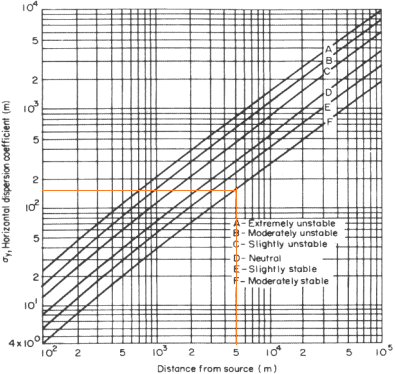 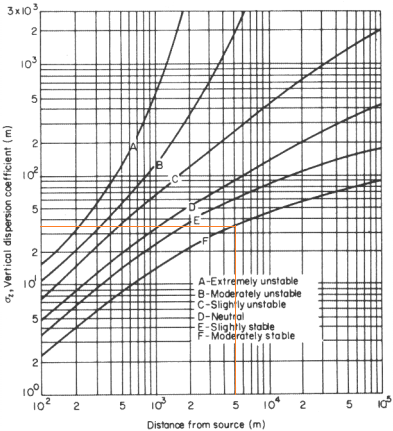

$\sigma_y =$ 170; and $\sigma_z =$ 35 m; 

So, for dispersion factor


$$\frac{\chi }{Q}=\frac{1}{\pi \;\sigma_y \sigma_z \;u\;}$$
  
$$\left\lbrack \frac{s}{m^3 }\right\rbrack$$
 

u = 1;              % wind speed; m/s
% Q                 % radioactivity; Ci/s
% Chi               % Ci/m^3
  dnm = pi*sg_y*sg_z *u;
Ch_Q = 1/dnm        % s/m^3

Ch_Q = 5.9698e-05

**for x = 10 km**

x = 10e3;               % ; m
sg_y = F_y*x^F_ye       % ; m 

sg_y = 295.7585

sg_z = F_z*x^F_ze

sg_z = 51.1717

Now, for calculating dispersion factor-

u = 1;              % wind speed; m/s
% Q                 % radioactivity; Ci/s
% Chi               % Ci/m^3
  dnm = pi*sg_y*sg_z *u;
Ch_Q = 1/dnm        % s/m^3

Ch_Q = 2.1032e-05

Now, from the necessary figure from RSANS, we find the following-

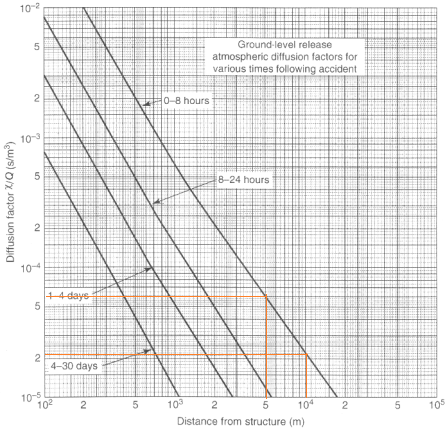

$\frac{\chi }{Q}=2\ldotp 1\times {10}^{-5} \;$ [s/m^3]

Which, closely matches with the calculated one

############## ############### ############### ############### 

## Prob-7.3a

We know,

Q = 200;            % MeV per fsn; MeV/fsn
 J_MeV = 1.6e-13;   % J/MeV
Q = Q *J_MeV        % ; W/fsn

Q = 3.2000e-11

Now, given

P = 3300e6;         % reactor power; Watt
n_f = P/Q           % no. of fissions; #

n_f = 1.0313e+20

So, let's find the no. of Iodines that's been produced from the fission-

y_I = 0.028;        % I-yield per fsn; #
n_I = n_f*y_I       % no. of I produced; #

n_I = 2.8875e+18

Now, some of these Iodines leaks into coolant with a given rate. So-

lf = 0.1*1e-2;      % leak fraction, I; #/hr
n_l = n_I*lf        % I leaked in hr;  #/hr

n_l = 2.8875e+15

N_I = n_l*30*24     % I leaked in a month; #

N_I = 2.0790e+18

Now, given here-

th_I = 8.02*24*60^2     % HL, I; s

th_I = 692928

l_I = log(2)/th_I       % decay const; s^-1

l_I = 1.0003e-06

Let's find the equilibrium activity-

A = N_I *l_I        % equilibrium activity; ds/s, Bq

A = 2.0797e+12

  Bq_Ci = 37e9;     % Bq/Ci
A = A /Bq_Ci        % ; Ci

A = 56.2070

(Ans)

############## ###############

## Prob-7.3b

Now, for 10% leak of coolant to the containment, no. of leaked I-131 would be-

N_lC = N_I *0.1;        % no. of I leaked within containment

As, all of it gets evaporated-

A_C = N_lC*l_I;         % I activity within containment; Bq
A_C = A_C/Bq_Ci         % ; Ci

A_C = 5.6207

Thence-

V_a = 5e4;          % air volume; m^3
A_Cn = A_C /V_a     % activty conc. of I in containment air; Ci/m^3

A_Cn = 1.1241e-04

(Ans)